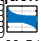

%prob_1a
N =50;
% Create the rectangular window
rectangular_window = rectwin(N);

% Compute the frequency response
freq_response_rectangular = freqz(rectangular_window, 1, 1024);

% Plot the magnitude of the frequency response
figure;
plot(linspace(0, 1, 1024), 20*log10(abs(freq_response_rectangular)));
title('Rectangular Window Frequency Response (Magnitude)');
xlabel('Normalized Frequency');
ylabel('Magnitude (dB)');
grid on;

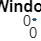

plot(rectangular_window)
title("Rectangular Window in time domain")
xlabel("Time(s)")
ylabel("Amplitude")

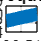


% Plot the phase of the frequency response
figure;
plot(linspace(0, 1, 1024), angle(freq_response_rectangular));
title('Rectangular Window Frequency Response (Phase)');
xlabel('Normalized Frequency');
ylabel('Phase (radians)');
grid on;

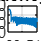



% Create the Hamming window
hamming_window = hamming(N);

% Compute the frequency response
freq_response_hamming = freqz(hamming_window, 1, 1024);

% Plot the magnitude of the frequency response

plot(linspace(0, 1, 1024), 20*log10(abs(freq_response_hamming)));
title('Hamming Window Frequency Response (Magnitude)');
xlabel('Normalized Frequency');
ylabel('Magnitude (dB)');
grid on;

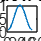

plot(hamming_window)
title("Hamming Window in time domain")
xlabel("Time(s)")
ylabel("Amplitude")

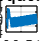


% Plot the phase of the frequency response
 
plot(linspace(0, 1, 1024), angle(freq_response_hamming));
title('Hamming Window Frequency Response (Phase)');
xlabel('Normalized Frequency');
ylabel('Phase (radians)');
grid on;

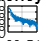


% Create the hanning window
hanning_window = hanning(N);

% Compute the frequency response
freq_response_hanning = freqz(hanning_window, 1, 1024);

% Plot the magnitude of the frequency response
 
plot(linspace(0, 1, 1024), 20*log10(abs(freq_response_hanning)));
title('Hanning Window Frequency Response (Magnitude)');
xlabel('Normalized Frequency');
ylabel('Magnitude (dB)');
grid on;

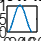

plot(hanning_window)
title("Hanning Window in time domain")
xlabel("Time(s)")
ylabel("Amplitude")

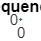


% Plot the phase of the frequency response
 
plot(linspace(0, 1, 1024), angle(freq_response_hanning));
title('Hanning Window Frequency Response (Phase)');
xlabel('Normalized Frequency');
ylabel('Phase (radians)');
grid on;

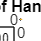


% Define the different lengths
N_values = [100,200,300];

% Number of points for the DFT
N_DFT = 1024;

% Create a frequency axis for the DFT
freq_axis = (0:N_DFT-1) / N_DFT;

% Loop through different lengths
for N = N_values
    % Generate the Blackman window
    hanning_window = hanning(N);
   
    % Generate a signal (e.g., a sine wave)
    t = 0:1/N:(N-1)/N;
    signal = 1; % Replace with your desired signal
   
    % Apply the Blackman window to the signal
    windowed_signal = signal .* (hanning_window');
   
    % Compute the DFT of the windowed signal
    dft = fft(windowed_signal, N_DFT);
   
    % Normalize the magnitude by the actual length
    normalized_magnitude = abs(dft) / N;
   
    % Plot the magnitude spectrum
    plot(freq_axis, 20*log10(normalized_magnitude));
    hold on;
end

% Label the plot and add a legend
title('Magnitude Spectrum of Hanning-Windowed Signal');
xlabel('Normalized Frequency');
ylabel('Magnitude (dB)');
legend('N=100','N=200','N=300');

% Set grid and hold off
grid on;
hold off;

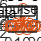

%prob2
% Define cutoff frequency and window length
alpha = 1;  % Adjust the value of alpha as needed
omega_c = pi /(alpha + 1);  % Cutoff frequency
N = 21;  % Window length

% Design the rectangular window filter
rectangular_window = ones(1, N);
rectangular_filter = fir1(N - 1, omega_c / pi, 'low', rectangular_window);

% Design the Hanning window filter
hanning_window = hanning(N);
hanning_filter = fir1(N - 1, omega_c / pi, 'low', hanning_window);

% Plot the impulse response of the two filters
figure;
stem(rectangular_filter);
legend("Impulse Response of Rectangular Window Filter'")
hold on;
title('Impulse Response of Window Filters');
stem(hanning_filter);
hold off;

xlabel('Sample Index');
ylabel('Amplitude');

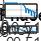



% Perform Bode analysis on the two filters
figure;
freqz(hanning_filter, 1, 1024); % Bode analysis for Hanning window filter
title('Bode Analysis of Hanning Window FIR Filter');

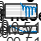


figure;
freqz(rectangular_filter, 1, 1024); % Bode analysis for Rectangular window filter
title('Bode Analysis of Rectangular Window FIR Filter');

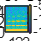

%prob3
% Load the audio file
[Y, Fs] = audioread('instru1.wav');
% Compute the DFT of the audio signal
N = length(Y);
dft = fft(Y, N);

figure
spectrogram(Y,hamming(512),256,512,Fs, 'yaxis');
title('Spectrogram of Original Audio');


% Compute the magnitude spectrum of the DFT
magnitude_spec = abs(dft);
% Calculate the fundamental frequency (excluding DC component)
[~, peak_index] = max(magnitude_spec(2:end));
fundamental_freq = peak_index * Fs / N

fundamental_freq = 524.3338

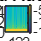

% Define the desired band-pass frequency range (in Hz)
low_cutoff = fundamental_freq - 20; % Adjust as needed
high_cutoff = fundamental_freq + 20; % Adjust as needed
% Normalize the cutoff frequencies to the Nyquist rate
ny_freq = Fs / 2;
low_cutoff_normalized = low_cutoff / ny_freq;
high_cutoff_normalized = high_cutoff / ny_freq;
% Design a band-pass FIR filter using the Hamming window
filter_order = 10; % Adjust the filter order as needed
filter_coefficients = fir1(filter_order, [low_cutoff_normalized, high_cutoff_normalized], 'bandpass', hamming(filter_order + 1));
% Apply the FIR filter to the audio signal
filtered_audio = filter(filter_coefficients, 1, Y);
% Normalize the filtered audio
filtered_audio = filtered_audio / max(abs(filtered_audio));
% Write the filtered audio to a new .wav file
audiowrite('filtered_instru_bandpass.wav', filtered_audio, Fs);
% Play the filtered audio
sound(filtered_audio, Fs);
% Compute and plot the spectrogram of the filtered audio
figure;
spectrogram(filtered_audio, hamming(512), 256, 512, Fs, 'yaxis');
title('Spectrogram of Band-Pass Filtered Audio (Fundamental and Harmonics)');